# Goal of thresholding: Isolate objects from the background

## Single thresholding: case study 1 - object is darker than the background

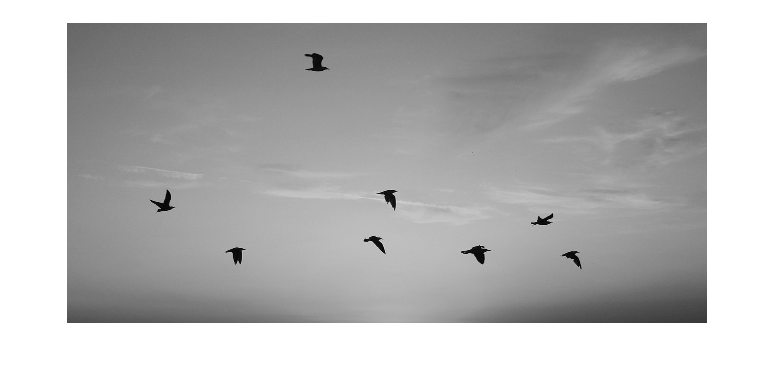

im = imread('flying.png');
figure, imshow(im)

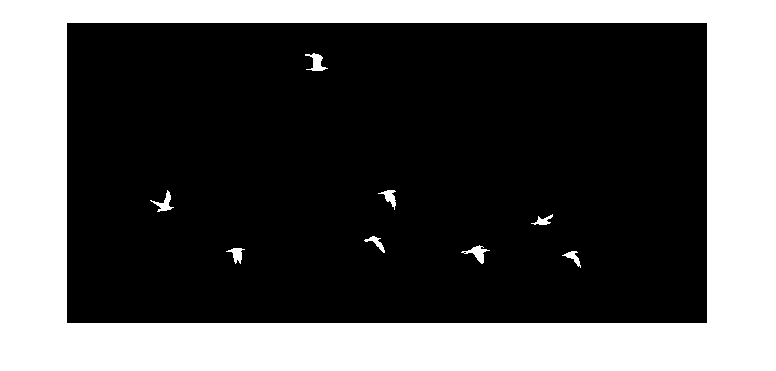

imt = im < 50; %flying
figure, imshow(imt);

## Single thresholding: case study 2 - object is lighter than the background

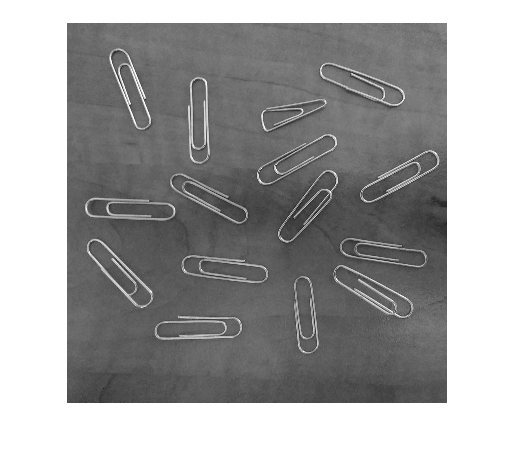

im = imread('paperclips.png');
figure, imshow(im)

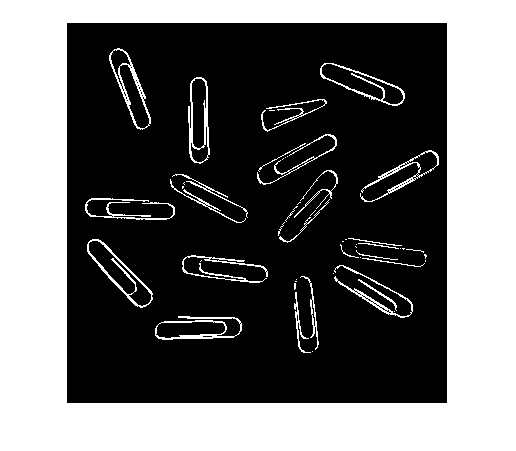

imt = im > 140; %paperclips
figure, imshow(imt);

## Single thresholding: case study 3 - Bring out the hidden detail

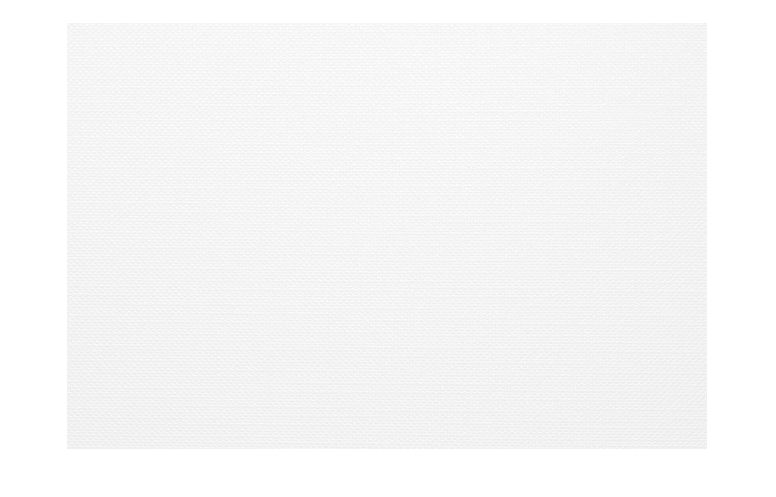

im = imread('handmade.png');
figure, imshow(im)

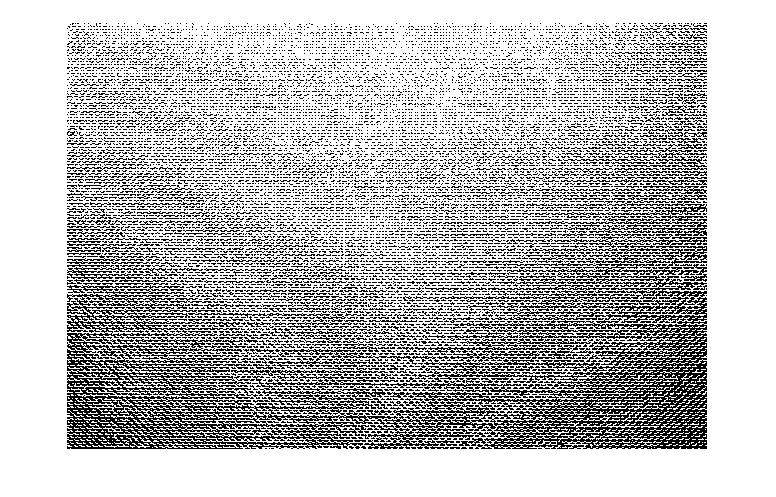

imt = im > 242; %handmade
figure, imshow(imt);

## Single thresholding: using inbuilt function called imbinarize

im = imread('flying.png');
imt = ~imbinarize(im, 0.6); 

**TODO 1**: **Type** the following command in the command window to learn more about thresholding: **help imbinarize. **Then, experiments with different values of the threshold. 

**TODO 2**: What does the ~ before the imbinarize do? Remove it and check the output! INVERSE

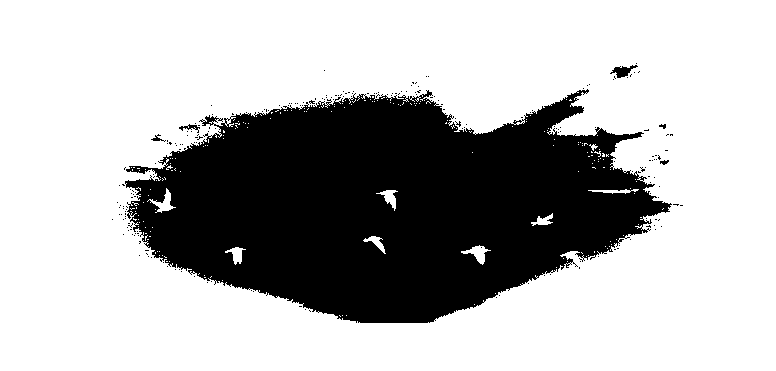

figure, imshow(imt)

## Single thresholding: another example using imbinarize

im = imread('paperclips.png');
imt = imbinarize(im, 0.55); %paperclips
figure, imshow(imt)

## Double thresholding (Use two thresholds T1 and T2)

–Pixel becomes white, if its gray level is between T1 and T2

–Black, if its gray level is otherwise

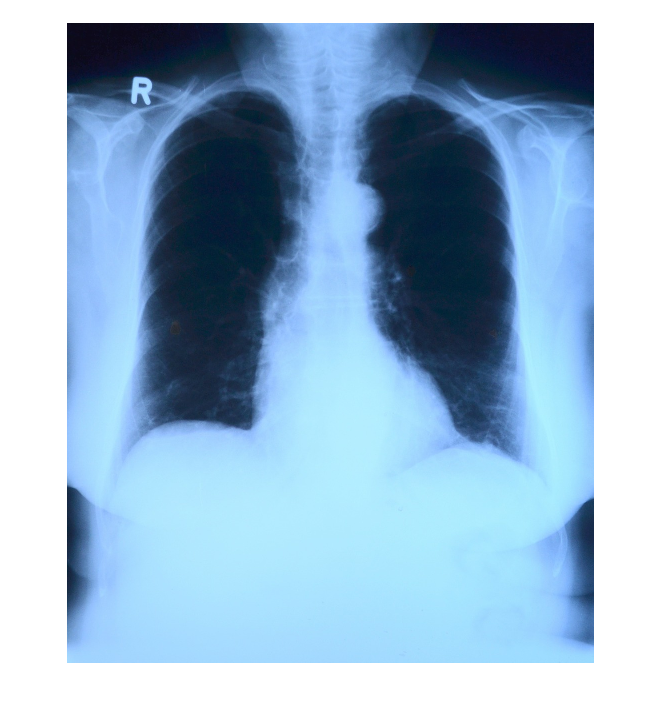

im = imread('xray.jpg');
figure, imshow(im) 

**TODO 1**: First run the code in this section and observe the output. 

**TODO 2**: Use only one of the thresholds below and observe the output. 

**TODO 3**: Bring the double thresholding back. But remove the rgb2gray in the above code and run this section again. How should the code change so that you don't get the error?

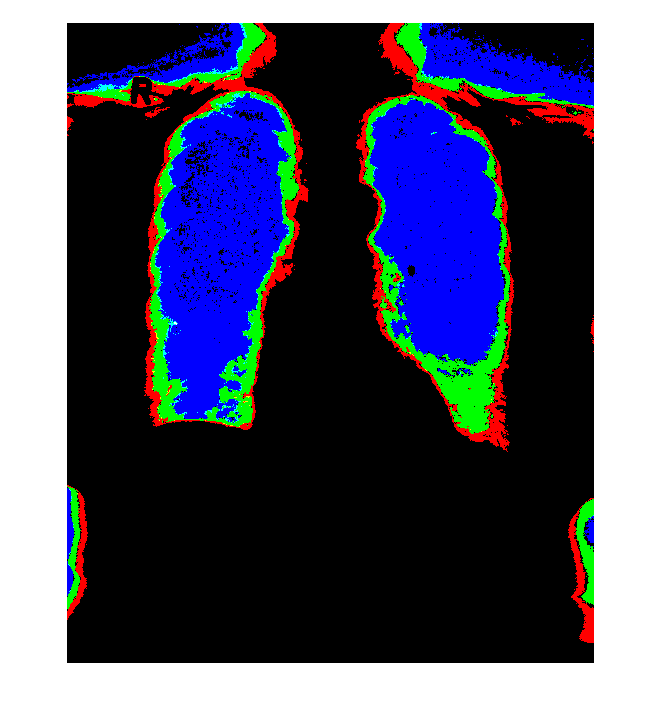

%imt = im < 80; %shows boundary of lungs and shoulder in the xray
imt = im > 50 & im < 80; %shows boundary of lungs and shoulder in the xray
imt2 = im2double(imt); 
figure, imshow(imt2); % Get row and column, and rgb each

## How to choose threshold. Plot histogram and observe the gray level that splits the two "hills" corresponding to the object and background

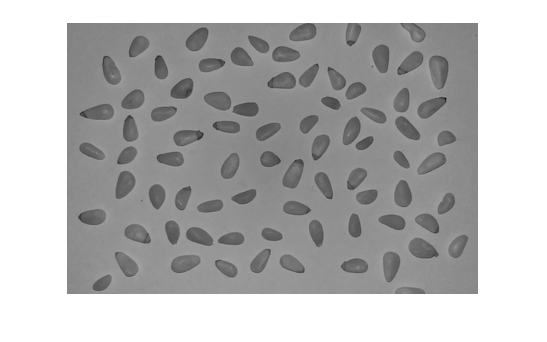

im = imread('pinenuts.png');
im2 = imread('paramecium1.png');
im3 = imread('blood.png');
im4 = imread('daisies.png');
figure, imshow(im)

%Plot histogram
[t, c] = imhist(im);
figure, plot(t)

The thresholds below are for **pinenuts.png** and are chosen to showcase the impact of choice of threshold.

**TODO 1**: Experiment with different threshold values. **Can you find the ideal one** that neatly separates the object from background? 

**TODO 2**: Repeat this for different images: paramecium1.png, blood.png, daisies.png 

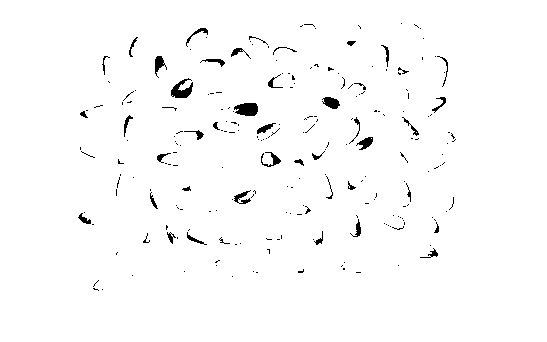

imt1 = imbinarize(im, 0.35); %Threshold too low for pinenuts.png
figure, imshow(imt1)

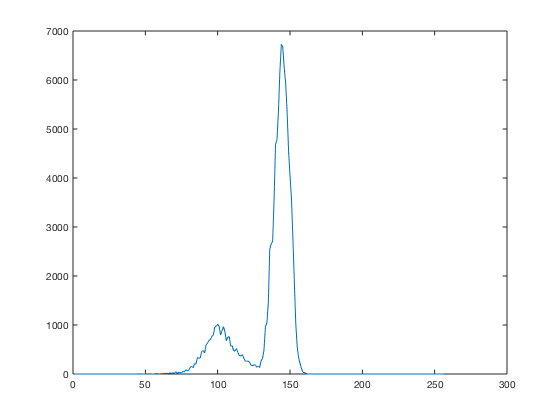

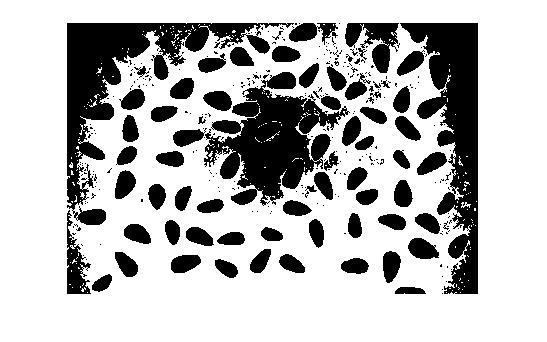

imt2 = imbinarize(im, 0.55); %Threshold too high for pinenuts.png
figure, imshow(imt2)

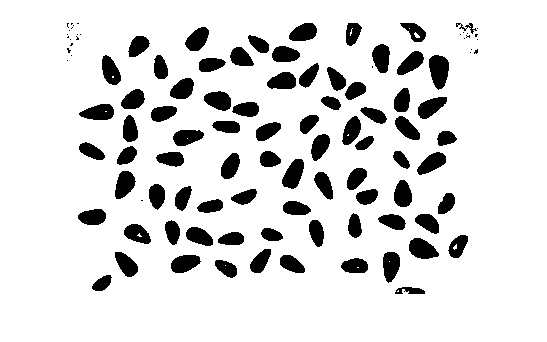

% TODO 1
imt3 = imbinarize(im, 129/255); % 0.50 for pinenuts
figure, imshow(imt3)

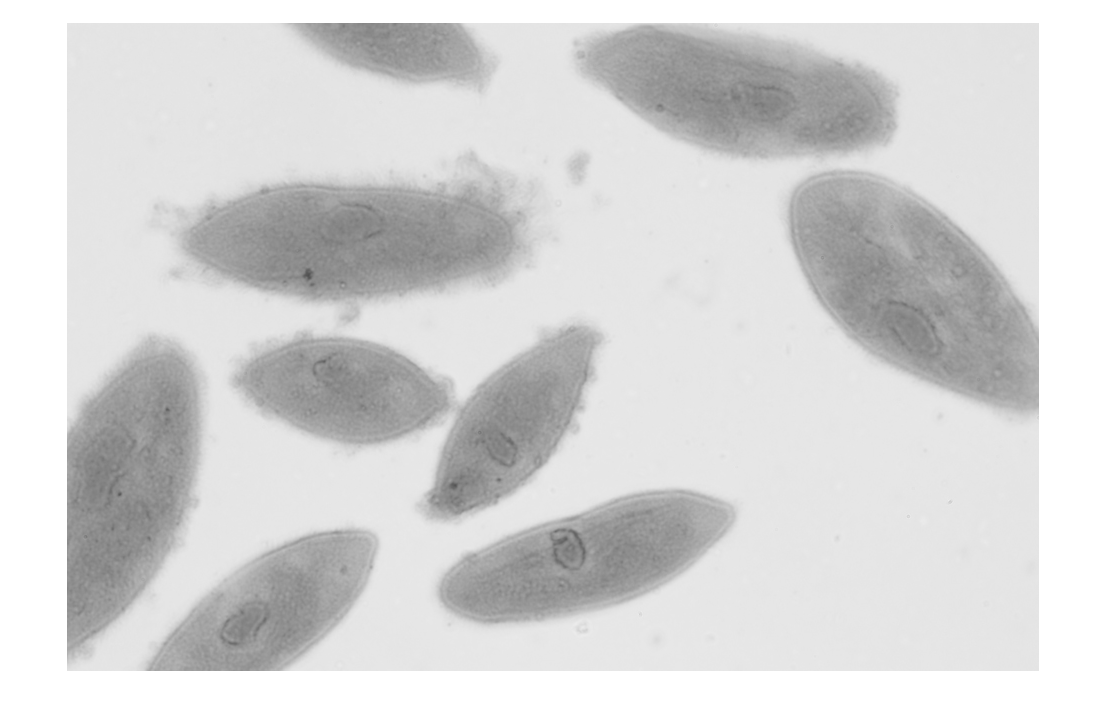


% TODO 2

%Plot histogram for paramecium1
figure, imshow(im2);

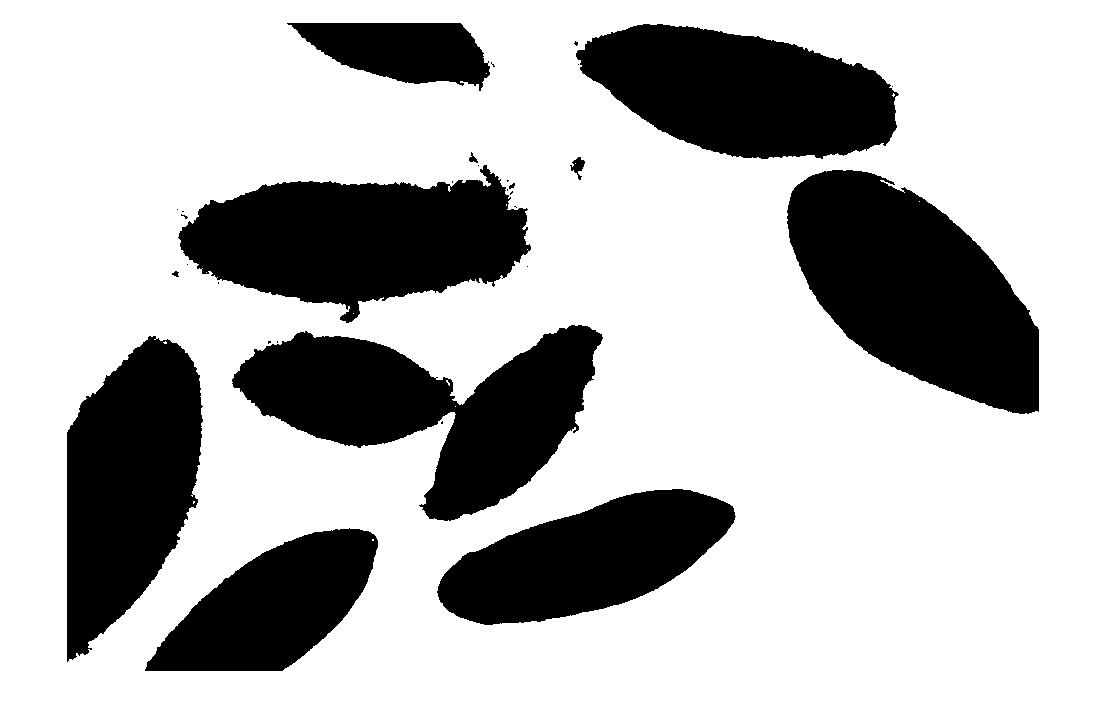

[t1, c1] = imhist(im2);
figure, plot(t1)

% Threshold for paramecium1
thresh_para = imbinarize(im2, 201/255); % 0.788
figure, imshow(thresh_para)

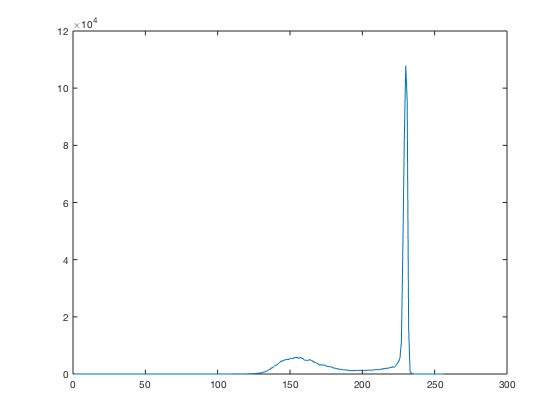

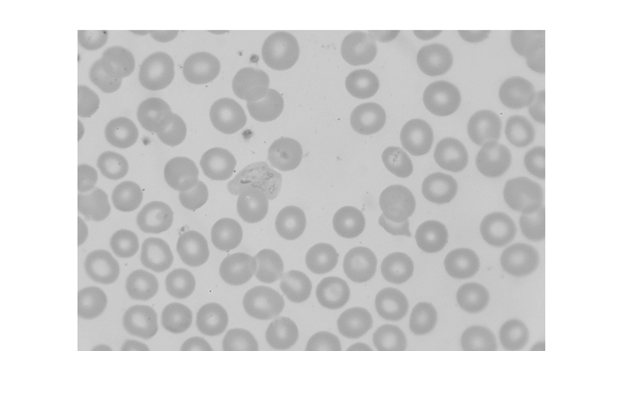


%Plot histogram for blood
figure, imshow(im3);

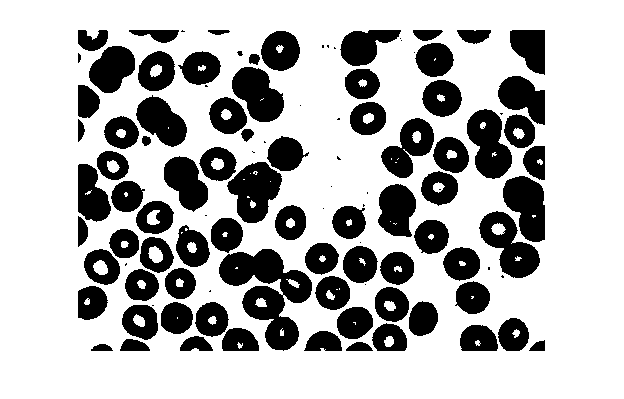

[t2, c2] = imhist(im3);
figure, plot(t2)

% Threshold for blood
thresh_blood = imbinarize(im3, 191/255); % 0.749
figure, imshow(thresh_blood)

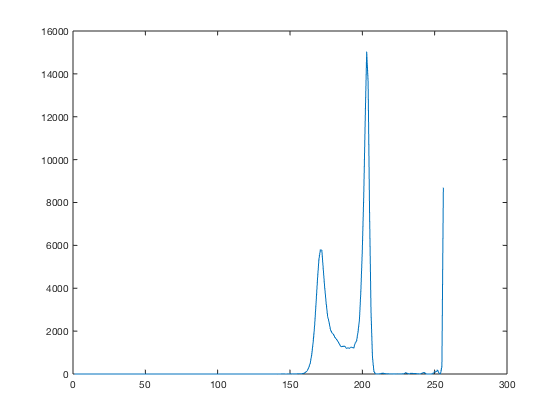

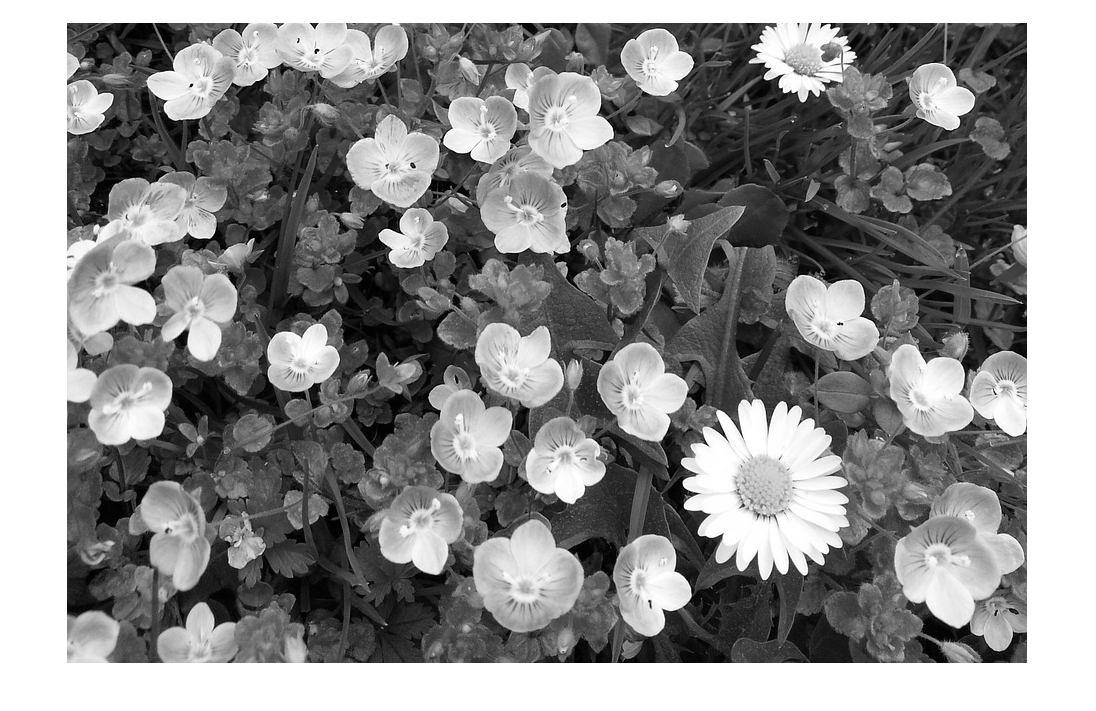


% Plot histogram for daisies
figure, imshow(im4);

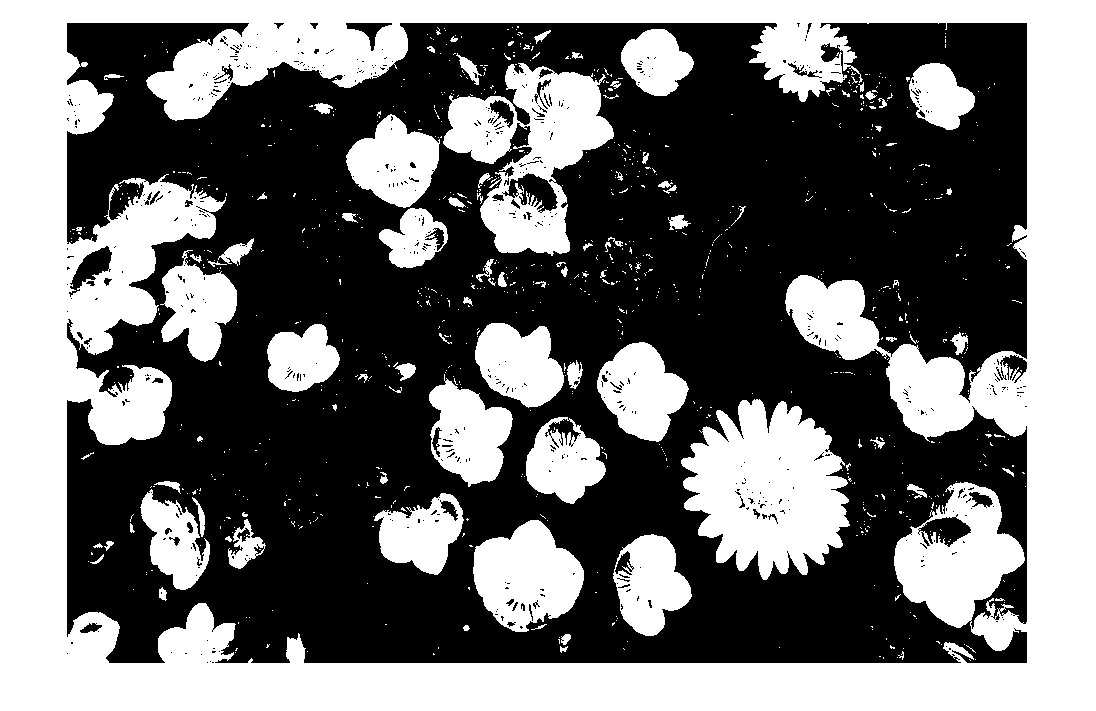

[t3, c3] = imhist(im4);
figure, plot(t3)
% Threshold for daisies
thres_daisy = imbinarize(im4, 151/255);
figure, imshow(thres_daisy)

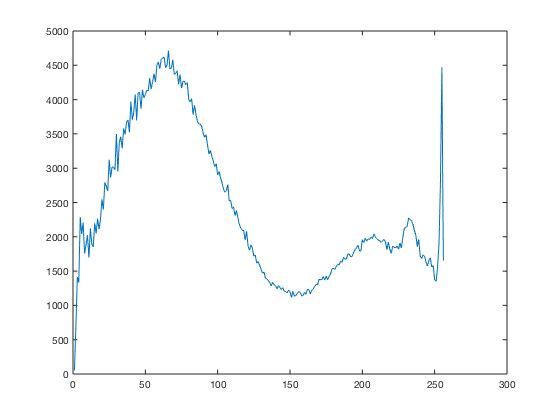

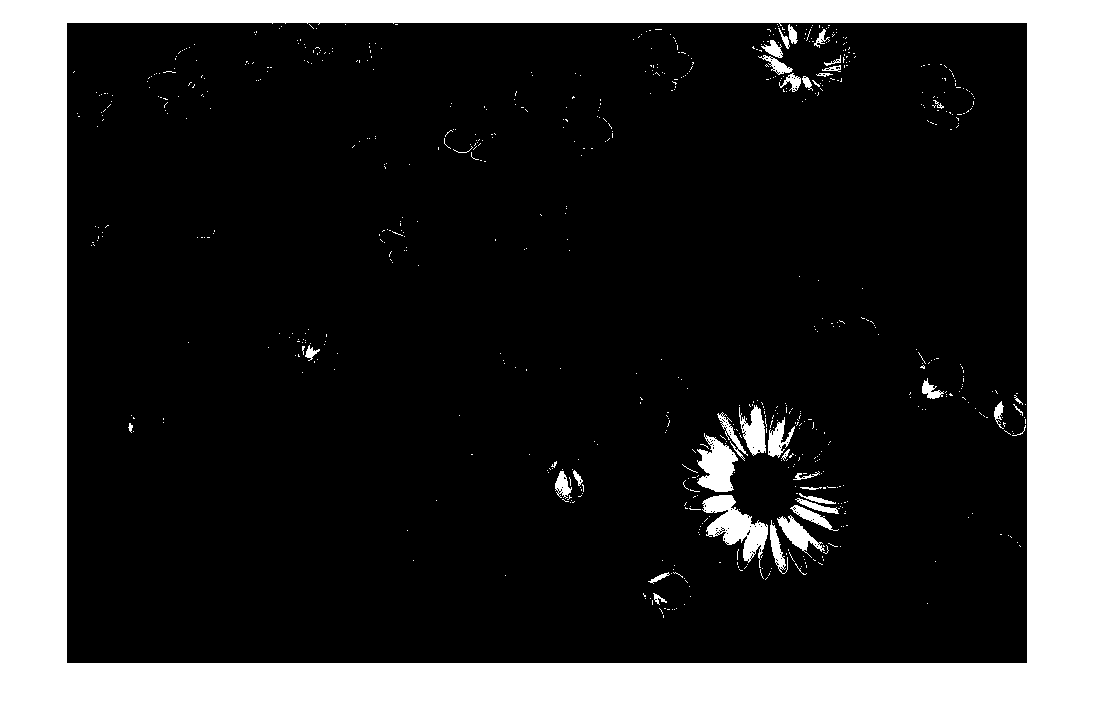


% Just the white flowers?
thres_daisy_w = imbinarize(im4, 251/255);
figure, imshow(thres_daisy_w)

## Calculate Threshold level produced automatically by "Otsu Method".

Otsu method: Determines a threshold so as to maximize the “*inter-class variance”: average distance between object and background pixels*

level = graythresh(im) %Computes threshold automatically using the Otsu Method

level = 0.4745

Note, for pinenuts.png, how gray level 0.4745*255 = 121 occurs neatly between the two "hills". This is the threshold that imbinarize uses if no argument is provided

**TODO**: Compare the threshold you got in the previous section through trial and error with that gotten here by the Otsu method. Pat your back if you were close!

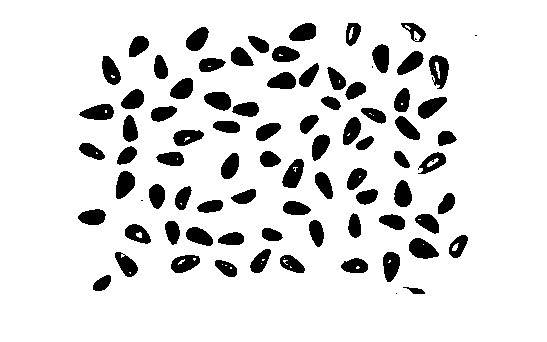

imb = imbinarize(im); %Uses Otsu method to perform thresholding
figure, imshow(imb);

figure, imshow(imt3);